优化工具箱实例

山东理工大学 数学院  周世祥 shixiangbupt@qq.com

Optimization Toolbox™ 提供了多个函数，这些函数可在满足约束的同时求出可最小化或最大化目标的参数。该工具箱包含适用于下列各项的求解器：线性规划 (LP)、混合整数线性规划 (MILP)、二次规划 (QP)、二阶锥规划 (SOCP)、非线性规划 (NLP)、约束线性最小二乘、非线性最小二乘和非线性方程。

您可以用函数和矩阵来定义优化问题，也可以通过指定反映底层数学关系的变量表达式来定义。您可以使用目标函数和约束函数的自动微分来更快地获得更准确的解。

[https://ww2.mathworks.cn/help/optim/getting-started-with-optimization-toolbox.html](https://ww2.mathworks.cn/help/optim/getting-started-with-optimization-toolbox.html)

查看工具箱中函数

help optim

  Optimization Toolbox
  Version 8.4 (R2019b) 18-Jul-2019 
 
  Nonlinear minimization of functions.
    fminbnd      - Scalar bounded nonlinear function minimization.
    fmincon      - Multidimensional constrained nonlinear minimization.
    fminsearch   - Multidimensional unconstrained nonlinear minimization, 
                   by Nelder-Mead direct search method.
    fminunc      - Multidimensional unconstrained nonlinear minimization.
    fseminf      - Multidimensional constrained minimization, semi-infinite 
                   constraints.
 
  Nonlinear minimization of multi-objective functions.
    fgoalattain  - Multidimensional goal attainment optimization 
    fminimax     - Multidimensional minimax optimization.
         
  Linear l

% 优化工具箱名称为optim.m

使用type命令得到工具箱函数的清单

type optim\contents


% Optimization Toolbox
% Version 8.4 (R2019b) 18-Jul-2019 
%
% Nonlinear minimization of functions.
%   fminbnd      - Scalar bounded nonlinear function minimization.
%   fmincon      - Multidimensional constrained nonlinear minimization.
%   fminsearch   - Multidimensional unconstrained nonlinear minimization, 
%                  by Nelder-Mead direct search method.
%   fminunc      - Multidimensional unconstrained nonlinear minimization.
%   fseminf      - Multidimensional constrained minimization, semi-infinite 
%                  constraints.
%
% Nonlinear minimization of multi-objective functions.
%   fgoalattain  - Multidimensional goal attainment optimization 
%   fminimax     - Multidimensional minimax optimization.
%        
% Linear least squares (of matrix problems).
%   lsqlin       - Linear least squares with linear constraints.
%   lsqnonneg    - Linear least squares with nonnegativity constraints.
%
% Nonlinear least squares (of functions).
%   lsqcurvefit  - Nonlinear 

可以求解线性规划，非线性规划，多目标规划。具体包括，线性，非线性最小化，最大最小化，二次规划，半无限问题。线性，非线性方程组求解，线性，非线性最小二乘问题。

###  一、工具箱中的函数

无约束非线性极小值 fminunc, fminsearch

一元函数无约束问题求解（fminbnd）%不一定是一次函数

****fminbnd的算法是基于黄金分割法和二次插值法，它要求目标函数必须是连续函数，并可能只给出局部最优解**

 fminbnd

约束非线性极小值fmincon

线性规划linprog

二次规划quadprog

多目标规划 fgoalattain

极大极小约束 fminimax

线性方程求解 \

标量非线性方程求解 fzero

非线性方程求解 fsolve

教程演示：tutdemo

演示过程菜单 optdemo

求解整数规划 officeassign

目标到达举例 goaldemo

无约束非线性最小化进行分子求解  molecule

马戏团帐篷问题---二次规划 circustent

二、优化函数变量

A,b 矩阵A和向量b分别为线性不等式约束的系数矩阵和右端项；

Aeq，beq：矩阵Aeq和向量beq分别为线性方程约束的系数矩阵和右端项；

C，d：矩阵C和向量d分别为超定或不定线性系统方程组的系数和进行求解的右端项；

f：线性方程或二次方程中线性项的系数向量；

H：二次方程中的二次项系数；

lb，ub：变量的上下界；

fun：待优化的函数；

nonlcon：计算非线性不等式和等式；

options：优化选项参数结构；

x0：初始点；

输出：

x：由优化函数求得的解；

fval：解x处的目标函数值；

exitflag：退出条件；

output：包含优化结果信息的输出结构；

lambda：解x处的拉格朗日乘子；

grad：解x处函数fun的梯度值；

hessian：解x处函数fun的海森矩阵；

jacobian：解x处函数fun的雅可比矩阵；

maxfval：解x处函数的最大值；

residual：解x处的残差值；

resnorm：解x处残差的平方范数

三、优化参数

Diagnostics：打印进行最小化或求解的诊断信息；

Display：值为off，不显示输出，值位iter，显示迭代信息，final时只显示结果，notify，函数不收敛时输出；

GradObj：用户定义的目标函数的梯度；

Hessian：用户定义的目标函数的海森矩阵；

LevenbergMarquardt：用Levenberg-Marquardt方法代替Gauss-Newton法；

MaxFunEvals：允许进行函数评价的最大次数；

MaxIter：允许进行迭代的最大次数；

TolX：X处的终止容限；

TolFun：函数值的终止容限；

optimavar函数用于创建优化变量，优化变量时一个符号对象，根据变量为目标函数和问题约束创建表达式。调用格式为：

x=optimvar(name) %创建优化变量x

x=optimvar(name,n) %创建优化变量x,x为n*1向量

例：

x=optimvar('x',5)%创建一个名为x的5*1优化变量向量x

x =   5×1 OptimizationVariable 数组 - 属性:

  Array-wide properties:
          Name: 'x'
          Type: 'continuous'
    IndexNames: {{}  {}}

  Elementwise properties:
    LowerBound: [5×1 double]
    UpperBound: [5×1 double]

  See variables with show.
  See bounds with showbounds.


五、参数设置

optimoptions函数的功能时创建优化选项

利用optimset可以创建和编辑参数结构，利用optimget函数可以获得options优化参数。

options = optimoptions(@fminimax,'ConstraintTolerance',1e7, 'DiffMaxChange',15000)   

options =   fminimax options:

   Set properties:
          ConstraintTolerance: 10000000

   Default properties:
    AbsoluteMaxObjectiveCount: 0
                      Display: 'final'
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
            FunctionTolerance: 1.000000000000000e-06
       MaxFunctionEvaluations: '100*numberOfVariables'
                MaxIterations: 400
          OptimalityTolerance: 1.000000000000000e-06
                    OutputFcn: []
                      PlotFcn: []
    SpecifyConstraintGradient: 0
     SpecifyObjectiveGradient: 0
                StepTolerance: 1.000000000000000e-06
                     TypicalX: 'ones(numberOfVariables,1)'
                  UseParallel: 0


% 为fminimax解算器创建优化选项，
% 不同的结算器可以设置的属性不同，设置约束冲突的终止容差，默认值为1e6；有限差分梯度变量，默认值是inf。

optimset   % 没有任何输入输出参数，显示一张完整的带有有效值的参数列表。

演示以下实例

options = optimset('Display','iter','TolFun',1e-8)  

options = 包含以下字段的 struct :
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: 1.000000000000000e-08
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                Larg

%创建一个称为options的优化选项结构，
% 其中显示参数设为'iter'，TolFun参数设置为1e-8。

optimget函数

val = optimget(options,'Display') 

val = 'iter'

% 显示优化参数options返回到options结构中

六、模型输入时需要注意的问题

目标函数最小化，fminbnd，fminsearch，fmincon，fgoalattain，fminmax，lsqnonlin都要求目标函数最小化，如果要求最大化目标，可以在函数前面加负号。

约束非正，要求非线性不等式约束的形式为$C_i \left(x\right)\le 0$;

避免使用全局变量：如果非要用，加global定义。

利用句柄传递函数：

fhandle = @humps;   
% humps是非线性函数，使用该函数构造函数句柄，
% 也将传递函数内所有变量。
x= fminbnd (fhandle, 0,1) 

x =    0.637008734044374


% 将刚创建的函数句柄传递给fminbnd函数，
% 然后在区间[0,1]上进行最小化

%用句柄将一个函数传递给另一个函数
x = fminbnd (@humps, 0,1) % 将刚创建的函数句柄传递

x =    0.637008734044374


% 给fminbnd函数，然后在区间[0,1]上进行最小化

优化算法简介

利用优化工具箱，可以求解线性规划，非线性规划，多目标规划，还有线性，非线性最小二乘问题，方程求解，曲线拟合，二次规划等问题中大型课题的求解方法。

参数优化问题

求一组设计参数$x=\left(x_1 ,x_2 ,\cdots ,x_n \right)$,以满足在某种意义上最优。

等式约束条件：$c_i \left(x\right)=0,i=1,2,\cdots ,m_e$

不等式约束：$c_i \left(x\right)\le 0,i=m_e +1,\cdots ,m$

带参数有界约束，一般模型如下：


$$\begin{array}{l}
{\mathrm{lim}}_{x\in R^n } f\left(x\right)\\
c_i \left(x\right)=0,i=1,\cdots \;,m_e \\
c_i \left(x\right)\le 0,i=m_e +1,\cdots ,m\\
\mathrm{lb}\le x\le \mathrm{ub}
\end{array}$$


无约束优化问题

梯度法使用函数的斜率信息给出搜索方向。一个简单的方法是沿负梯度方向$-\nabla f\left(x\right)$搜索.

拟牛顿法：本质上是建立每次迭代的曲率信息，以此来解决如下形式的二次模型问题：

${\mathrm{lim}}_{x\in R^n } f\left(x\right)=\frac{1}{2}x^T H_x +b^T x+c$,$H$为目标函数的海森矩阵，$H$为正定，b为常数向量，c为常数。这个问题的最优解在$x$的梯度为零的点处。

$\nabla f\left(x^* \right)={H\;x}^* +b=0$,

从而最优解为：$x^* =-H^{-1} b$

牛顿法直接计算$H$，并使用线搜索策略沿下降方向经过一定次数的迭代后确定最小值，为了得到矩阵$H$需要进行大量的计算，拟牛顿法则不同，它通过使用$f\left(x\right)$和它的梯度来修正$H$的近似值。

拟牛顿法发展到现在已经出现很多经典实用的海森矩阵修正方法。BFGS方法被认为是解决一般问题最有效的方法，修正公式如下：


$$H_{k+1} =H_k +\frac{{\mathrm{qkq}}_k^T }{q_k^T s_k }-\frac{{H_k^T {s_k^T s}_k H_k } }{s_k^T H_k s_k^T }$$


$s_k =x_{k+1} -x_k$,$q_k =\nabla f\left(x_{k+1} \right)-\nabla f\left(x_k \right)$

在函数fminunc中使用拟牛顿法，确定搜索方向，完成对海森矩阵的修正，搜索方向可以选择由BFGS或DFP来确定。海森矩阵总是正定的，使得搜索方向总是保持为下降方向。

x=fminunc(fun,x0) %从点x0开始，找到函数的局部最小值x。点x0可以是标量，矢量或矩阵

[x,fval,exitflag,output,grad,hessian]=fminunc()

%exitflag 1时收敛到目标函数最优解处，2时X的变化小于规定的容许范围，3目标函数值的变化小于规定的容许范围，0达到最大迭代次数或达到函数评价，-1时算法由输出函数终止，-2线搜索在当前方向找不到可接受的点；

output.iterations:迭代次数

output.algorithm：所用算法、

例如，求$F=\mathrm{sin}\left(x\right)+3$的最小值点

function F = demfun(x)

%This is a function for demostration

    F = sin(x) + 3;

X = fminunc(@demfun,2)  % 调用函数句柄求x=2时函数的极值


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


X =    4.712388941554389


例如，在给定的梯度下求$F=\sin \left(x\right)+3$的最小值点

function [f,g]= demfun0(x)

%This is a function for demostration      

      f = sin(x) + 3;

      g = cos(x);

options = optimset('GradObj','on');  
% 创建使用目标函数函数梯度的优化选项options结构体，
% 默认梯度的设置false会导致fminunc使用有限差分来估计梯度。
x = fminunc('demfun0',4,options)  


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =    4.712388980401212


% 从点x0=4开始，使用options结构体计算函数的局部最小值x

例题，求函数$y=5x_1^2 +x_2^2$的极小点

x = fminunc(@(x) 5*x(1)^2 + x(2)^2,[5;1])  


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x = 	1.0e+-6 *

  -0.789786368430667
  -0.070242292426205


% 从点x0=[5 1]开始，计算函数的局部最小值x

例，求函数$f=ax_1^2 {+2x_1 x_2 +x}_2^2$的极小点

function [f,g] = demfun00(x,a)

%This is a function for demostration    

    f = a*x(1)^2 + 2*x(1)*x(2) + x(2)^2; % 定义函数

    g = [2*a*x(1) + 2*x(2)               % 定义梯度

           2*x(1) + 2*x(2)];

a = 3;   % 定义参数值 
options = optimset('GradObj','on'); 
% 使用目标函数函数梯度的优化选项options结构体
x = fminunc(@(x) demfun00(x,a),[1;1],options)  


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x = 	1.0e+-6 *

   0.268996384641323
  -0.225316971919441


% 从点x0=[1 1]开始，使用options结构体计算函数的局部最小值x

fminsearch函数使用无导数法计算无约束的多变量函数的最小值

例：$y=4x_1^2 +6x_2^2 +x_1 -x_2 +2$极小点

options = optimset('PlotFcns',@optimplotfval);   
% 设置选项，以在每次迭代时绘制目标函数图。
fun=@(x) 4*x(1)^2+6*x(2)^2+x(1)-x(2)+2;  
% 从点x0=[5 1]开始，计算函数的局部最小值x
x = fminunc(fun,[0;1],options)  


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =   -0.124999997416406
   0.083333326985970


% 从点x0=[5 1]开始，计算函数的局部最小值x

求函数的优化问题


$$f\left(x\right)={\left(x_1 -0\ldotp 5\right)}^2 +{\left(x_2 -0\ldotp 5\right)}^2 +{\left(x_3 -0\ldotp 5\right)}^2$$



$$K_1 \left(x,w_1 \right)=\mathrm{sin}\left(w_1 x_1 \right)\mathrm{cos}\left(w_1 x_2 \right)-\frac{1}{1000}{\left(w_1 -0\ldotp 5\right)}^2 -\mathrm{sin}\left(w_1 x_3 \right)-x_3 \le 1$$



$$K_2 \left(x,w_2 \right)=\mathrm{sin}\left(w_1 x_2 \right)\mathrm{cos}\left(w_2 x_2 \right)-\frac{1}{1000}{\left(w_2 -0\ldotp 5\right)}^2 -\mathrm{sin}\left(w_2 x_3 \right)-x_3 \le 1$$



$$1\le w_1 \le 100,1\le w_2 \le 100$$


先建立目标函数文件

function f=funsif(x)

%This is a function for demonstration

f=sum((x-0.5).^2);

编辑约束函数文件

function [C,Ceq,K1,K2,S] = funsifcon(X,S)

%This is a function for demonstration

% 初始化样本间距：

if  isnan(S(1,1))   % 确定第一行第一列矩阵元素是否为 NaN

     S = [0.2  0; 0.2  0];

end

% 产生样本集：

w1 = 1:S(1,1):100;   % 创建向量 

w2 = 1:S(2,1):100;

% 将约束方程化为标准形式，计算半无限约束：

K1 = sin(w1*X(1)).*cos(w1*X(2)) - 1/1000*(w1-50).^2 -sin(w1*X(3))-X(3)-1;

K2 = sin(w2*X(2)).*cos(w2*X(1)) - 1/1000*(w2-50).^2 -sin(w2*X(3))-X(3)-1;

% 无非线性约束：

C = [ ]; Ceq=[ ];

% 绘制半无限约束图形

plot(w1,K1,'-',w2,K2,':'),title('Semi-infinite constraints')

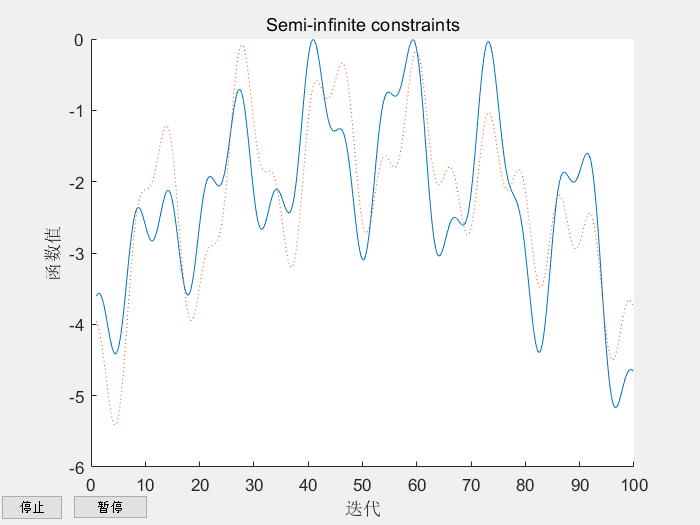


Local minimum possible. Constraints satisfied.

fseminf stopped because the size of the current search direction is less than
twice the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


X =    0.667472169549488
   0.301177805789812
   0.402237198268986


FVAL =    0.077134757886464


EXITFLAG =      4


OUTPUT = 包含以下字段的 struct:
         iterations: 8
          funcCount: 32
       lssteplength: 1
           stepsize: 2.277307760635262e-04
          algorithm: 'active-set'
      firstorderopt: 0.043729091307823
    constrviolation: -0.005824517038512
            message: '↵Local minimum possible. Constraints satisfied.↵↵fseminf stopped because the size of the current search direction is less than↵twice the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current search direction, 1.744858e-04,↵is less than 2*options.StepTolerance = 1.000000e-04, and the maximum constraint ↵violation, -5.824517e-03, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'


LAMBDA = 包含以下字段的 struct:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: [0×1 double]
    ineqnonlin: [0×1 double]



x0 = [0.5; 0.2; 0.3];      % 定义初始值
[X,FVAL,EXITFLAG,OUTPUT,LAMBDA] = fseminf(@funsif,x0,2,@funsifcon)  

% 计算半无限约束多变量非线性函数的最小值

[https://ww2.mathworks.cn/help/optim/ug/fseminf.html](https://ww2.mathworks.cn/help/optim/ug/fseminf.html)

工具箱中的实例

[https://ww2.mathworks.cn/help/optim/ug/optimization-toolbox-tutorial.html](https://ww2.mathworks.cn/help/optim/ug/optimization-toolbox-tutorial.html)

**无约束优化示例**

假设要求下面这个函数的最小值：


$$x\;\mathrm{exp}\left(-\left(x^2 +y^2 \right)\right)+\left(x^2 +y^2 \right)/20$$


绘制函数以查看它具有最小值的位置。

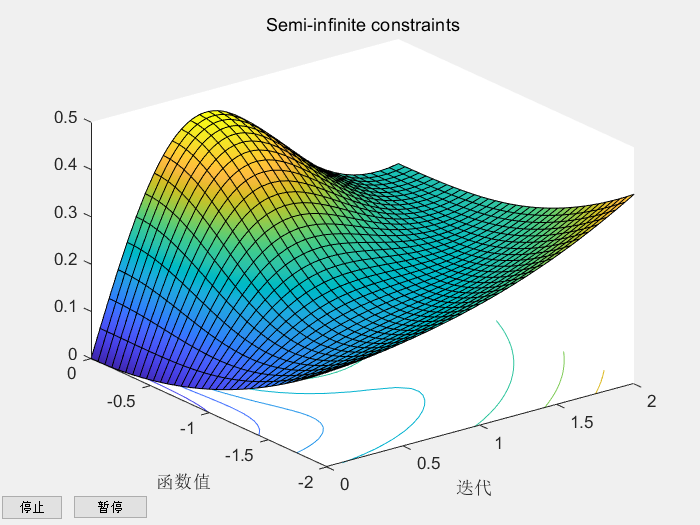

f = @(x,y) x.*exp(-x.^2-y.^2)+(x.^2+y.^2)/20;
fsurf(f,[-2,2],'ShowContours','on')

绘图显示最小值在点 (-1/2,0) 附近。

通常将目标函数定义为一个 MATLAB® 文件。在这种情况下，函数足够简单，可以定义为匿名函数。

fun = @(x) f(x(1),x(2));

为找到解设置一个初始点。

x0 = [-.5; 0];

设置优化选项以使用 `fminunc` 默认 `'quasi-newton'` 算法。此步骤可确保教程在每个 MATLAB 版本中的工作方式是相同的。

options = optimoptions('fminunc','Algorithm','quasi-newton');

在求解器执行计算时查看迭代。

options.Display = 'iter';

调用 `fminunc`，它是一个无约束非线性最小化求解函数。

[x, fval, exitflag, output] = fminunc(fun,x0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3          -0.3769                         0.339
     1           6        -0.379694              1          0.286  
     2           9        -0.405023              1         0.0284  
     3          12        -0.405233              1        0.00386  
     4          15        -0.405237              1       3.17e-05  
     5          18        -0.405237              1       3.35e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

显示求解器找到的解。

uncx = x

uncx =   -0.669071831647573
   0.000000004602598


查看在该解处的函数值。

uncf = fval

uncf =   -0.405236870266690


这些示例使用函数计算的次数来衡量求解效率。查看函数计算的总次数。

output.funcCount

ans =     18


**带附加参数的无约束优化示例**

接下来，将额外参数作为附加参数传递给目标函数，首先使用 MATLAB 文件，然后使用嵌套函数。

以上一示例中的目标函数为例。


$$f\left(x,y\right)=x\;\mathrm{exp}\left(-\left(x^2 +y^2 \right)\right)+\left(x^2 +y^2 \right)/20$$


用 (a,b,c) 对该函数进行参数化，如下所示：

`f``(``x``,``y``,``a``,``b``,``c``)``=``(``x``−``a``)``exp``(``−``(``(``x``−``a``)^2``+``(``y``−``b``)^2``)``)``+``(``(``x``−``a``)^2``+``(``y``−``b``)^2``)``/``c``.`

此函数是原始目标函数的移位和缩放版本。**MATLAB 文件函数**

假设有一个名为 `bowlpeakfun` 的 MATLAB 文件目标函数，定义如下。

`function y = bowlpeakfun(x, a, b, c)`

`%BOWLPEAKFUN Objective function for parameter passing in TUTDEMO.`

`%   Copyright 2008 The MathWorks, Inc.`

`y = (x(1)-a).*exp(-((x(1)-a).^2+(x(2)-b).^2))+((x(1)-a).^2+(x(2)-b).^2)/c;`

type bowlpeakfun


function y = bowlpeakfun(x, a, b, c)
%BOWLPEAKFUN Objective function for parameter passing in TUTDEMO.

%   Copyright 2008 The MathWorks, Inc.

y = (x(1)-a).*exp(-((x(1)-a).^2+(x(2)-b).^2))+((x(1)-a).^2+(x(2)-b).^2)/c;


定义参数。

a = 2;
b = 3;
c = 10;

创建 MATLAB 文件的匿名函数句柄。

f = @(x)bowlpeakfun(x,a,b,c)

f = 包含以下值的 function_handle :
    @(x)bowlpeakfun(x,a,b,c)


调用 `fminunc` 以求最小值。

x0 = [-.5; 0];
options = optimoptions('fminunc','Algorithm','quasi-newton');
[x, fval] = fminunc(f,x0,options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =    1.363872771337888
   3.000000300431893


fval =   -0.383961517686543


**嵌套函数**

假设有 `nestedbowlpeak` 函数，它将目标实现为一个嵌套函数。

type nestedbowlpeak


function [x,fval] =  nestedbowlpeak(a,b,c,x0,options)
%NESTEDBOWLPEAK Nested function for parameter passing in TUTDEMO.

%   Copyright 2008 The MathWorks, Inc.

[x,fval] = fminunc(@nestedfun,x0,options);  
    function y = nestedfun(x)
      y = (x(1)-a).*exp(-((x(1)-a).^2+(x(2)-b).^2))+((x(1)-a).^2+(x(2)-b).^2)/c;    
    end
end


`function [x,fval] =  nestedbowlpeak(a,b,c,x0,options)`

`%NESTEDBOWLPEAK Nested function for parameter passing in TUTDEMO.`

`%   Copyright 2008 The MathWorks, Inc.`

`[x,fval] = fminunc(@nestedfun,x0,options);  `

`    function y = nestedfun(x)`

`      y = (x(1)-a).*exp(-((x(1)-a).^2+(x(2)-b).^2))+((x(1)-a).^2+(x(2)-b).^2)/c;    `

`    end`

`end`

参数 (a,b,c) 对于嵌套目标函数 `nestedfun` 可见。外部函数 `nestedbowlpeak` 调用 `fminunc` 并传递目标函数 `nestedfun`。

定义参数、初始估计值和选项：

a = 2;
b = 3;
c = 10;
x0 = [-.5; 0];
options = optimoptions('fminunc','Algorithm','quasi-newton');

运行优化：

[x,fval] =  nestedbowlpeak(a,b,c,x0,options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =    1.363872771337888
   3.000000300431893


fval =   -0.383961517686543


这两种方法产生相同的答案，因此您可以使用您认为最方便的一种。

**约束优化示例：不相等性**

还是上面那个问题，现在我们给它添加一个约束条件：

`minimize ``x ``exp``(``−``(``x^``2``+``y^``2``)``)``+``(``x^``2``+``y^``2``)``/``2``0``,`

`subject to ``x``y``/``2``+``(``x``+``2``)^2``+``(``y``−``2``)^2``/``2``≤``2``.`

约束集是一个倾斜椭圆的内部。查看与倾斜椭圆一起绘制的目标函数的轮廓。

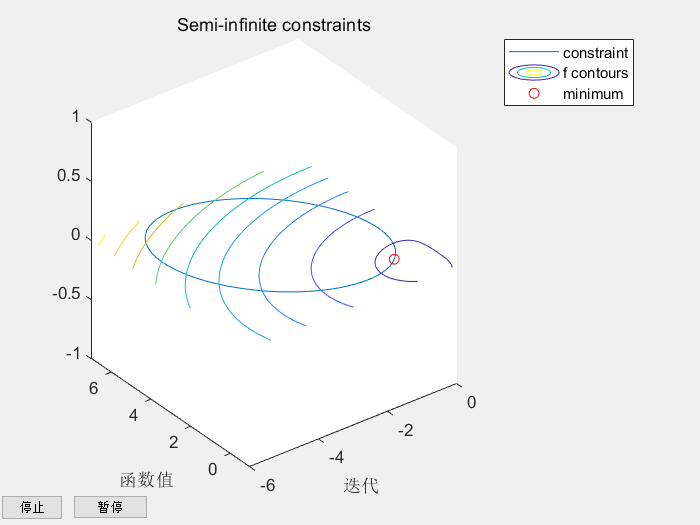

f = @(x,y) x.*exp(-x.^2-y.^2)+(x.^2+y.^2)/20;
g = @(x,y) x.*y/2+(x+2).^2+(y-2).^2/2-2;
fimplicit(g)
axis([-6 0 -1 7])
hold on
fcontour(f)
plot(-.9727,.4685,'ro');
legend('constraint','f contours','minimum');
hold off

绘图显示椭圆内目标函数的最小值出现在椭圆的右下角附近。在计算绘制的最小值之前，猜测解出现在以下位置。

x0 = [-2 1];

设置优化选项以使用内点算法，并显示每次迭代的结果。

options = optimoptions('fmincon','Algorithm','interior-point','Display','iter');

求解器要求非线性约束函数给出两个输出：一个用于非线性不等式，一个用于非线性等式。为了给出这两个输出，我们使用 `deal` 函数来编写约束。

gfun = @(x) deal(g(x(1),x(2)),[]);

调用非线性约束求解器。问题没有线性等式、不等式或边界，因此对这些参数传递 [ ]。

[x,fval,exitflag,output] = fmincon(fun,x0,[],[],[],[],[],[],gfun,options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.365241e-01    0.000e+00    1.972e-01
    1       6    1.748504e-01    0.000e+00    1.734e-01    2.260e-01
    2      10   -1.570560e-01    0.000e+00    2.608e-01    9.347e-01
    3      14   -6.629160e-02    0.000e+00    1.241e-01    3.103e-01
    4      17   -1.584082e-01    0.000e+00    7.934e-02    1.826e-01
    5      20   -2.349124e-01    0.000e+00    1.912e-02    1.571e-01
    6      23   -2.255299e-01    0.000e+00    1.955e-02    1.993e-02
    7      26   -2.444225e-01    0.000e+00    4.293e-03    3.821e-02
    8      29   -2.446931e-01    0.000e+00    8.100e-04    4.035e-03
    9      32   -2.446933e-01    0.000e+00    1.999e-04    8.126e-04
   10      35   -2.448531e-01    0.000e+00    4.004e-05    3.289e-04
   11      38   -2.448927e-01    0.000e+00    4.036e-07    8.156e-05



显示求解器找到的解。

x

x =   -0.972742693534711   0.468569967776063


查看在该解处的函数值。

fval

fval =   -0.244892738234539


查看函数计算的总次数。

Fevals = output.funcCount

Fevals =     38


在解处满足不等式约束。

[c, ceq] = gfun(x)

c =     -2.460796955539024e-06



ceq =

     []



由于 c(x) 接近 0，约束是*活动的*，这意味着它影响解。回想一下无约束解。

uncx

uncx =   -0.669071831647573
   0.000000004602598


回想一下无约束目标函数。

uncf

uncf =   -0.405236870266690


查看约束使解发生了多大的移动并使目标函数的值增加了多少。

fval-uncf

ans =    0.160344132032152


**约束优化示例：用户提供的梯度**

通过提供梯度，可以更高效、更准确地求解优化问题。与前一个示例一样，此示例求解不等式约束问题

`minimize ``x ``exp``(``−``(``x^``2``+``y^``2``)``)``+``(``x^``2``+``y^``2``)``/``2``0``,`

`subject to ``x``y``/``2``+``(``x``+``2``)^2``+``(``y``−``2``)^2``/``2``≤``2``.`

为了给 `fmincon` 提供 f(x) 的梯度，以 MATLAB 文件的形式编写目标函数。

type onehump


function [f,gf] = onehump(x)
% ONEHUMP Helper function for Tutorial for the Optimization Toolbox demo

%   Copyright 2008-2009 The MathWorks, Inc.

r = x(1)^2 + x(2)^2;
s = exp(-r);
f = x(1)*s+r/20;

if nargout > 1
   gf = [(1-2*x(1)^2)*s+x(1)/10;
       -2*x(1)*x(2)*s+x(2)/10];
end


`function [f,gf] = onehump(x)`

`% ONEHUMP Helper function for Tutorial for the Optimization Toolbox demo`

`%   Copyright 2008-2009 The MathWorks, Inc.`

`r = x(1)^2 + x(2)^2;`

`s = exp(-r);`

`f = x(1)*s+r/20;`

`if nargout > 1`

`   gf = [(1-2*x(1)^2)*s+x(1)/10;`

`       -2*x(1)*x(2)*s+x(2)/10];`

`end`

约束及其梯度包含在 MATLAB 文件 `tiltellipse` 中。

type tiltellipse


function [c,ceq,gc,gceq] = tiltellipse(x)
% TILTELLIPSE Helper function for Tutorial for the Optimization Toolbox demo

%   Copyright 2008-2009 The MathWorks, Inc.

c = x(1)*x(2)/2 + (x(1)+2)^2 + (x(2)-2)^2/2 - 2;
ceq = [];

if nargout > 2
   gc = [x(2)/2+2*(x(1)+2);
       x(1)/2+x(2)-2];
   gceq = [];
end


为找到解设置一个初始点。

x0 = [-2; 1];

设置优化选项，以使用与上例相同的算法进行比较。

options = optimoptions('fmincon','Algorithm','interior-point');

设置在目标函数和约束函数中使用梯度信息的选项。注意：必须启用这些选项，否则梯度信息将被忽略。

options = optimoptions(options,...
    'SpecifyObjectiveGradient',true,...
    'SpecifyConstraintGradient',true);

由于 `fmincon` 不需要使用有限差分来估计梯度，因此求解器应具有更少的函数计数。设置选项以在每次迭代时显示结果。

options.Display = 'iter';

调用求解器。

[x,fval,exitflag,output] = fmincon(@onehump,x0,[],[],[],[],[],[], ...
                                   @tiltellipse,options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.365241e-01    0.000e+00    1.972e-01
    1       2    1.748504e-01    0.000e+00    1.734e-01    2.260e-01
    2       4   -1.570560e-01    0.000e+00    2.608e-01    9.347e-01
    3       6   -6.629161e-02    0.000e+00    1.241e-01    3.103e-01
    4       7   -1.584082e-01    0.000e+00    7.934e-02    1.826e-01
    5       8   -2.349124e-01    0.000e+00    1.912e-02    1.571e-01
    6       9   -2.255299e-01    0.000e+00    1.955e-02    1.993e-02
    7      10   -2.444225e-01    0.000e+00    4.293e-03    3.821e-02
    8      11   -2.446931e-01    0.000e+00    8.100e-04    4.035e-03
    9      12   -2.446933e-01    0.000e+00    1.999e-04    8.126e-04
   10      13   -2.448531e-01    0.000e+00    4.004e-05    3.289e-04
   11      14   -2.448927e-01    0.000e+00    4.036e-07    8.156e-05



`fmincon` 在前面的示例中对梯度进行了很好的估计，因此在此示例中的迭代与之相似。

显示求解器找到的解。

xold = x

xold =   -0.972742694488360
   0.468569966693330


查看在该解处的函数值。

minfval = fval

minfval =   -0.244892738234872


 查看函数计算的总次数。

Fgradevals = output.funcCount

Fgradevals =     14


将此数字与无梯度的函数计算次数进行比较。

Fevals

Fevals =     38


**约束优化示例：更改默认终止容差**

此示例继续使用梯度，并求解同一约束问题

`minimize ``x``exp``(``−``(``x^``2``+``y^``2``)``)``+``(``x^``2``+``y^``2``)``/``2``0``,`

`subject to ``x``y``/``2``+``(``x``+``2``)^2``+``(``y``−``2``)^2``/``2``≤``2`。

在本例中，您可以通过覆盖默认终止条件（`options.StepTolerance` 和 `options.OptimalityTolerance`）来获得更准确的解。`fmincon` 内点算法的默认值为 `options.StepTolerance = 1e-10` 和 `options.OptimalityTolerance = 1e-6`。

覆盖这两个默认终止条件。

options = optimoptions(options,...
    'StepTolerance',1e-15,...
    'OptimalityTolerance',1e-8);

调用求解器。

[x,fval,exitflag,output] = fmincon(@onehump,x0,[],[],[],[],[],[], ...
                                   @tiltellipse,options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.365241e-01    0.000e+00    1.972e-01
    1       2    1.748504e-01    0.000e+00    1.734e-01    2.260e-01
    2       4   -1.570560e-01    0.000e+00    2.608e-01    9.347e-01
    3       6   -6.629161e-02    0.000e+00    1.241e-01    3.103e-01
    4       7   -1.584082e-01    0.000e+00    7.934e-02    1.826e-01
    5       8   -2.349124e-01    0.000e+00    1.912e-02    1.571e-01
    6       9   -2.255299e-01    0.000e+00    1.955e-02    1.993e-02
    7      10   -2.444225e-01    0.000e+00    4.293e-03    3.821e-02
    8      11   -2.446931e-01    0.000e+00    8.100e-04    4.035e-03
    9      12   -2.446933e-01    0.000e+00    1.999e-04    8.126e-04
   10      13   -2.448531e-01    0.000e+00    4.004e-05    3.289e-04
   11      14   -2.448927e-01    0.000e+00    4.036e-07    8.156e-05
   12      15   -2.448931e-01    0.000e+00    4

为了更准确地查看新容差造成的差异，在解中显示更多小数位数。

                               format long

显示求解器找到的解。

                               x

x =   -0.972742227363546
   0.468569289098341


将这些值与前面示例中的值进行比较。

                               xold

xold =   -0.972742694488360
   0.468569966693330


确定值的变化。

   x - xold

ans = 	1.0e+-6 *

   0.467124813607889
  -0.677594988840458


查看在该解处的函数值。

   fval

fval =   -0.244893137879894


查看解改进了多少。

   fval - minfval

ans =     -3.996450221588344e-07


答案为负值，因为新解更小。

查看函数计算的总次数。

   output.funcCount

ans =     15


将此数字与使用用户提供的梯度和默认容差求解的示例中的函数计算数进行比较。

   Fgradevals

Fgradevals =     14


**约束优化示例：用户提供的 Hessian 矩阵**

如果除了梯度之外，您还提供 Hessian 矩阵，求解器会更加精确和高效。

`fmincon` 的内点算法将 Hessian 矩阵作为一个单独的函数（不是目标函数的一部分）。Hessian 函数 H(x,lambda) 计算拉格朗日的 Hessian 矩阵；请参阅 [适用于 fmincon 内点算法的 Hessian 矩阵](https://ww2.mathworks.cn/help/optim/ug/writing-scalar-objective-functions.html#bu2xbye-1)。

求解器计算值 `lambda.ineqnonlin` 和 `lambda.eqlin`；您的 Hessian 函数会告知求解器如何使用这些值。

此示例有一个不等式约束，因此 Hessian 矩阵在 `hessfordemo` 函数中给出。

   type hessfordemo


function H = hessfordemo(x,lambda)
% HESSFORDEMO Helper function for Tutorial for the Optimization Toolbox demo

%   Copyright 2008-2009 The MathWorks, Inc.

s = exp(-(x(1)^2+x(2)^2));
H = [2*x(1)*(2*x(1)^2-3)*s+1/10, 2*x(2)*(2*x(1)^2-1)*s;
        2*x(2)*(2*x(1)^2-1)*s, 2*x(1)*(2*x(2)^2-1)*s+1/10];
hessc = [2,1/2;1/2,1];
H = H + lambda.ineqnonlin(1)*hessc;


`function H = hessfordemo(x,lambda)`

`% HESSFORDEMO Helper function for Tutorial for the Optimization Toolbox demo`

`%   Copyright 2008-2009 The MathWorks, Inc.`

`s = exp(-(x(1)^2+x(2)^2));`

`H = [2*x(1)*(2*x(1)^2-3)*s+1/10, 2*x(2)*(2*x(1)^2-1)*s;`

`        2*x(2)*(2*x(1)^2-1)*s, 2*x(1)*(2*x(2)^2-1)*s+1/10];`

`hessc = [2,1/2;1/2,1];`

`H = H + lambda.ineqnonlin(1)*hessc;`

为了使用 Hessian 矩阵，您需要适当地设置选项。

options = optimoptions('fmincon',...
    'Algorithm','interior-point',...
    'SpecifyConstraintGradient',true,...
    'SpecifyObjectiveGradient',true,...
    'HessianFcn',@hessfordemo);

容差设置为默认值，这样应得到更少的函数计数。设置选项以在每次迭代时显示结果。

   options.Display = 'iter';

调用求解器。

%[x,fval,exitflag,output] = fmincon(@onehump,x0,[],[],[],[],[],[], ...
%                                   @tiltellipse,options);
[x,fval,exitflag,output] = fmincon(@onehump,x0,[],[],[],[],[],[], ...
                                   @tiltellipse,options);                           

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.365241e-01    0.000e+00    1.972e-01
    1       3    5.821325e-02    0.000e+00    1.443e-01    8.728e-01
    2       5   -1.218829e-01    0.000e+00    1.007e-01    4.927e-01
    3       6   -1.421167e-01    0.000e+00    8.486e-02    5.165e-02
    4       7   -2.261916e-01    0.000e+00    1.989e-02    1.667e-01
    5       8   -2.433609e-01    0.000e+00    1.537e-03    3.486e-02
    6       9   -2.446875e-01    0.000e+00    2.057e-04    2.727e-03
    7      10   -2.448911e-01    0.000e+00    2.068e-06    4.191e-04
    8      11   -2.448931e-01    0.000e+00    2.001e-08    4.218e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


结果显示迭代有变化且次数更少。

显示求解器找到的解。

                               x

x =   -0.972742246093537
   0.468569316215571


查看在该解处的函数值。

                               fval

fval =   -0.244893121872758


查看函数计算的总次数。

                               output.funcCount

ans =     11


将此数字与仅使用梯度计算和相同默认容差求解的示例中的函数计算次数进行比较。 

Fgradevals

Fgradevals =     14


` 参考文献：`

`1.槐创锋，郝勇，Matlab 2020中文版从入门到精通，人民邮电出版社，2020年4月`